**FORMULATION OF RNA-FOLDING INTO ILP PROBLEM:**

`let us consider a binary variable P corresponding each and every pairs of nucleotide present in the given sequence, in such a way that the value of P(a,b) will be '1' if and only if there is an interaction possible between the `$a^{\textrm{th}}$` nucleotide and `$b^{\textrm{th}}$` nucleotide of the given nucleotide sequence and let us consider a matrix 'P' in order to store all the P(i,j) in an organised manner so as to make all P(i,j) values easily accesible.`

seq = 'UGACA';
n= length(seq);
rna_fold = optimproblem('ObjectiveSense','maximize');
vars = optimvar("vars",[n,n],"LowerBound",0,"Type","integer","UpperBound",1);

**Objective Function:**


$$\sum P\left(i,j\right)\;\forall \;\;i<j\;\textrm{and}\;i,j<\textrm{length}\left(\textrm{RNA}\;\textrm{sequence}\right)$$



$$\begin{array}{l}
\textrm{onjective}\;\textrm{function}\;:\sum P\left(i,j\right)\;+\sum P\left(i^{\prime } ,j^{\prime } \right)\;\;\\
\textrm{where},\textrm{sequence}\left(i,j\right)\in \;\left\lbrack \textrm{AU},\textrm{UA}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{sequence}\left(i^{\prime } ,j^{\prime } \right)\in \left\lbrack \textrm{CG},\textrm{GC}\right\rbrack 
\end{array}$$


%From the above sequence we are defining our required objective function.
sum = optimexpr;
for i=1:n
    for j=i:n
        sum = sum + vars(i,j);
    end
end
rna_fold.Objective = sum;

**Removing Repitition variables present in matrix:**

`In the case of RNA folding problem, a nucleotide cannot be paired with itself, hence, the variables 'P(i,j)' where 'i' and 'j' are equal actually make no sense. Also, we can observe that there is a redundancy in the variables, for example, the variables P(1,2) and P(2,1).let us consider only the upper triangular part of our matrix. Hence, the updated 'P' matrix turns out to be,`$P=\;\left\lbrack \begin{array}{ccccc}
0 & P_{12}  & P_{13}  & P_{14}  & P_{15} \\
0 & 0 & P_{23}  & P_{24}  & P_{25} \\
0 & 0 & 0 & P_{34}  & P_{35} \\
0 & 0 & 0 & 0 & P_{45} \\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$

list1 = [];
for i=1:n
    for j=1:n
        if i>=j
            eqn = vars(i,j)==0;
            list1 = [list1;eqn];
        end
    end
end
rna_fold.Constraints.neccesary = list1;

%Defining the required constraints for formulating the problem:

### `CONSTRAINT - 1`

`A nucleotide present in RNA sequence can only interact with it's complement present in the sequence.`


$$P\left(i,j\right)=0\;\;\forall \;\textrm{seq}\left(i\right),\textrm{seq}\left(j\right)\not\in \left\lbrack \textrm{"AU"},\textrm{"UA"},\textrm{"CG"},\textrm{"GC"}\right\rbrack$$


possible_pairs = ["AU","UA","CG","GC"];
eqnns1 = [];
for i=1:n
    for j=1:n
        if i<j
            if ~any(strcmp(strcat(seq(i),seq(j)),possible_pairs))
                eqn = vars(i,j) == 0;
                eqnns1 = [eqnns1;eqn];
            end 
        end
    end
end
rna_fold.Constraints.set1 = eqnns1;

### `CONSTRAINT - 2`

`A nucleotide present in RNA sequence can be paired with only one other nucleotide present in the sequence.`


$$\sum P\left(a\right)+\sum P\left(b\right)\le 1\;$$



$$\textrm{where},\;a=\left(i,j\right)\forall \;i<j\;\textrm{and}\;b=\left(j,i\right)\forall \;i>j$$


eqnns2 = [];
for i=1:n
    eqn = optimexpr;
    for j=1:n
        if i~=j
            if i<j
                eqn = eqn+vars(i,j);
            elseif i>j
                eqn = eqn+vars(j,i);
            end
        end
    end
    eqns = eqn<=1;
    eqnns2 = [eqnns2;eqns];
end
rna_fold.Constraints.set2 = eqnns2;

### `CONSTRAINT - 3`

`No two pairings or bonds present in an RNA sequence must cross each other, all the interactions must be in a nested manner.`


$$P\left(i,j\right)+P\left(i^{\prime } ,j^{\prime } \right)\le 1\;\;\;,\textrm{where}$$

$$i<i^{\prime } <j<j^{\prime } \;\textrm{and}\;i,i^{\prime } ,j,j^{\prime } <\textrm{length}\left(\textrm{RNA}\;\textrm{sequence}\right)$$


nums = nchoosek([1:length(seq)],4)

nums =      1     2     3     4
     1     2     3     5
     1     2     4     5
     1     3     4     5
     2     3     4     5


eqnns3 = [];
b = size(nums);
for i=(1:b(1))
    eqn = vars(nums(i,1),nums(i,3))+vars(nums(i,2),nums(i,4))<=1;
    eqnns3 = [eqnns3;eqn];
end
rna_fold.Constraints.set3 = eqnns3;

[sol,fval] = solve(rna_fold);

Solving problem using intlinprog.
LP:                Optimal objective value is -2.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 0 (the default value).
The intcon variables are integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



begin = [];
end1 = [];
for i=1:n
    for j=1:n
        if sol.vars(i,j)==1
            begin = [begin,i];
            end1 = [end1,j];
        end
    end
end
begin,end1;

begin =      1     2


## `DOT BRACKET NOTATION`

`In the dot-bracket notation, every nucleotide which is not paired or which is not interacting with any other nucleotide  must be represented as a dot and the nucleotides which are paired are represented by brackets.`

dot_bracket = '';
for i=1:length(seq)
    if ismember(i,begin)
        dot_bracket = [dot_bracket,'('];
    elseif ismember(i,end1)
        dot_bracket = [dot_bracket,')'];
    else
        dot_bracket = [dot_bracket,'.'];
    end
end

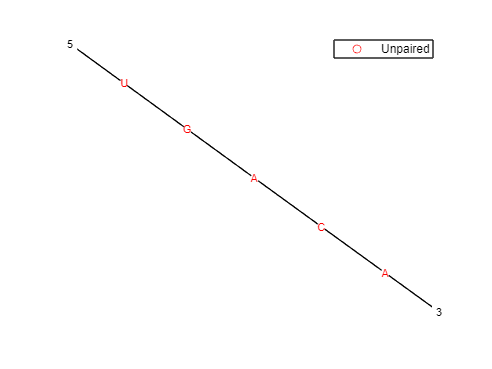

ss = rnafold(seq);
rnaplot(ss,'Format','Diagram','Sequence',seq)

**ADDING AN ADDITIONAL CONSTRAINT:**

`A nucleotide present in RNA sequence can interact with another nucleotide which is at least 4 nucleotides away.`

r1=[];
c1=[];
for i=1:n
    for j=1:n
        if j-i<=4
            r1 = [r1,i];
            c1 = [c1,j];
        end
    end
end
list2 = [];
for i = 1:length(r1)
    eqn = vars(r1(i),c1(i))==0;
    list2 = [list2;eqn];
end
rna_fold.Constraints.add1 = list2;
%Now we should make a change in objective function.
sum = optimexpr;
st_pairs = ["CG","GC"];
for i=1:n
    for j=i:n
        seq1 = strcat(seq(i),seq(j));
        if ~any(strcmp(seq1,st_pairs))
            sum = sum + 1.33*vars(i,j);
        else
            sum = sum + vars(i,j);
        end
    end
end
rna_fold.Objective = sum;

[sol,fval] = solve(rna_fold);

Solving problem using intlinprog.
LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 0 (the default value).
The intcon variables are integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



begin = [];
end1 = [];
for i=1:n
    for j=1:n
        if sol.vars(i,j)==1
            begin = [begin,i];
            end1 = [end1,j];
        end
    end
end

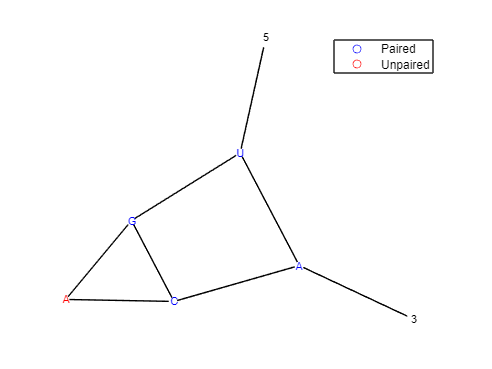

rnaplot(dot_bracket,'Format','Diagram','Sequence',seq)